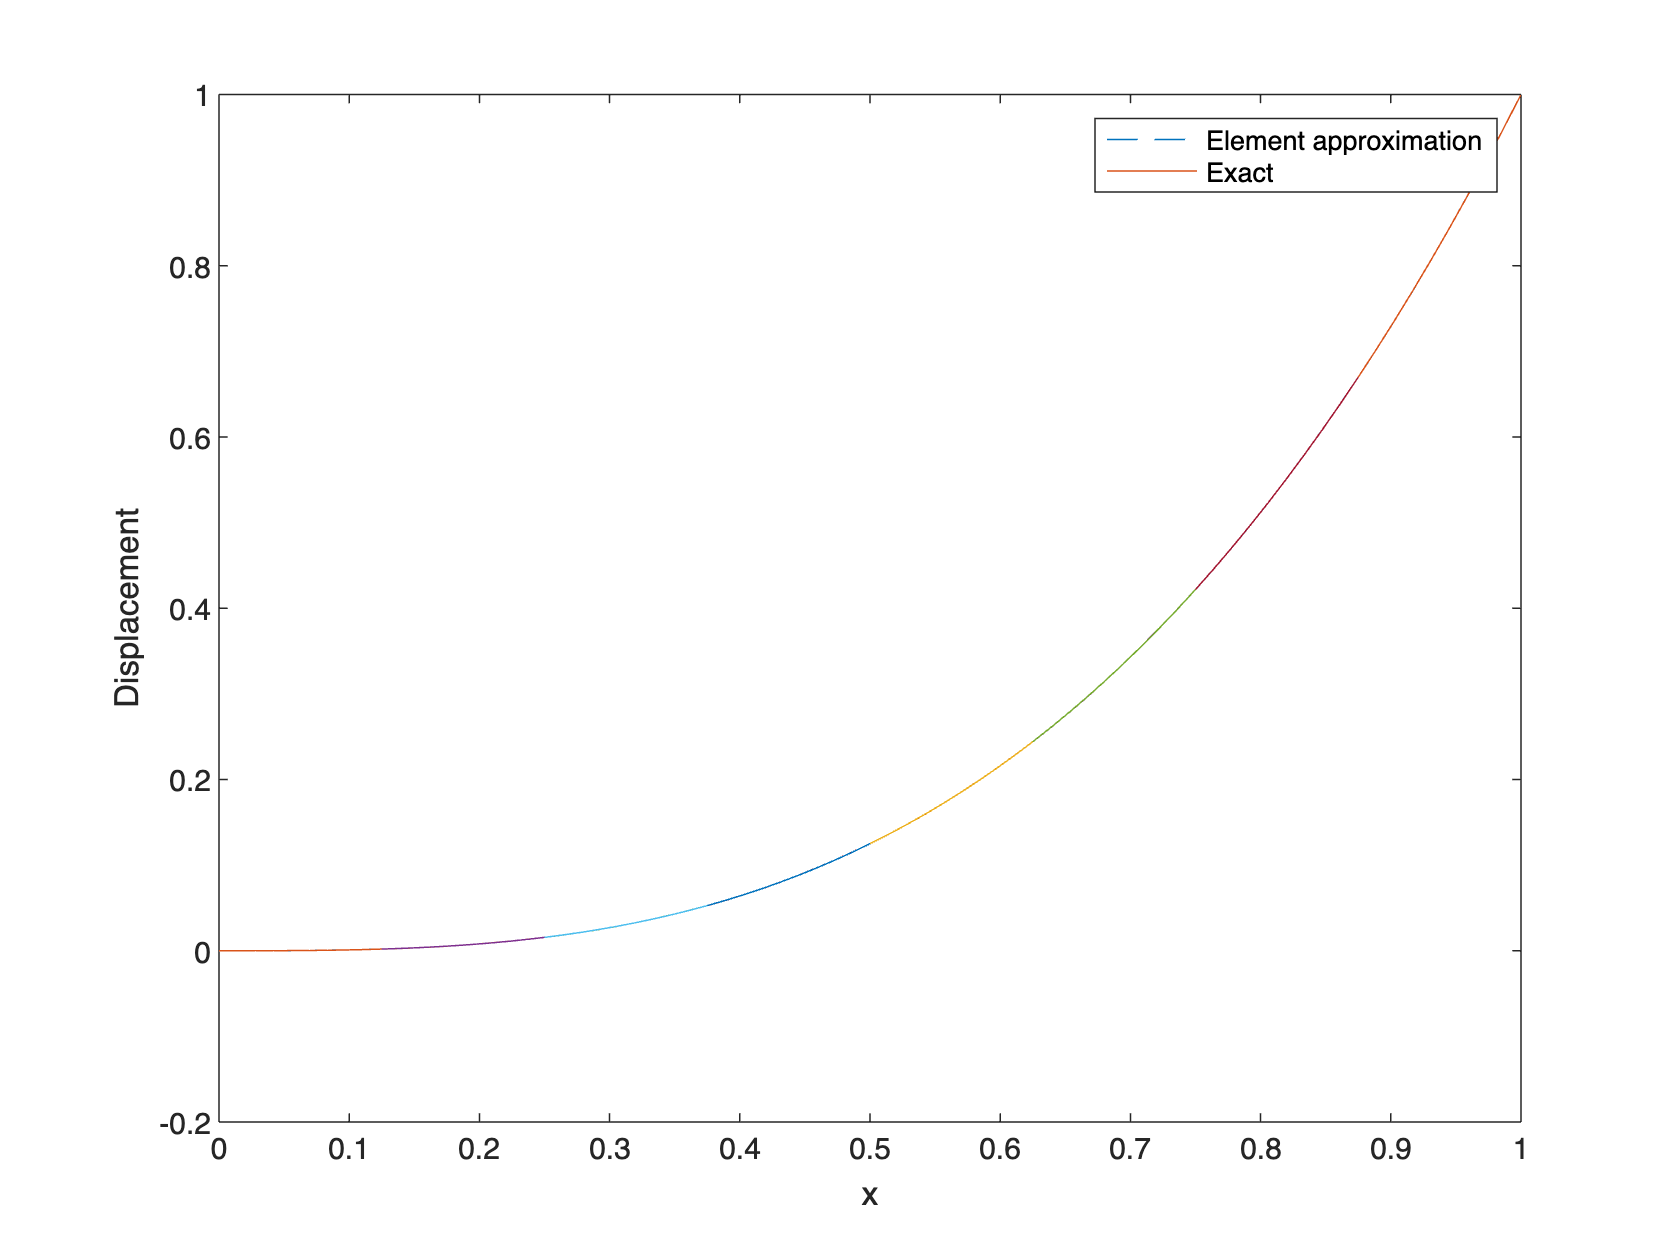

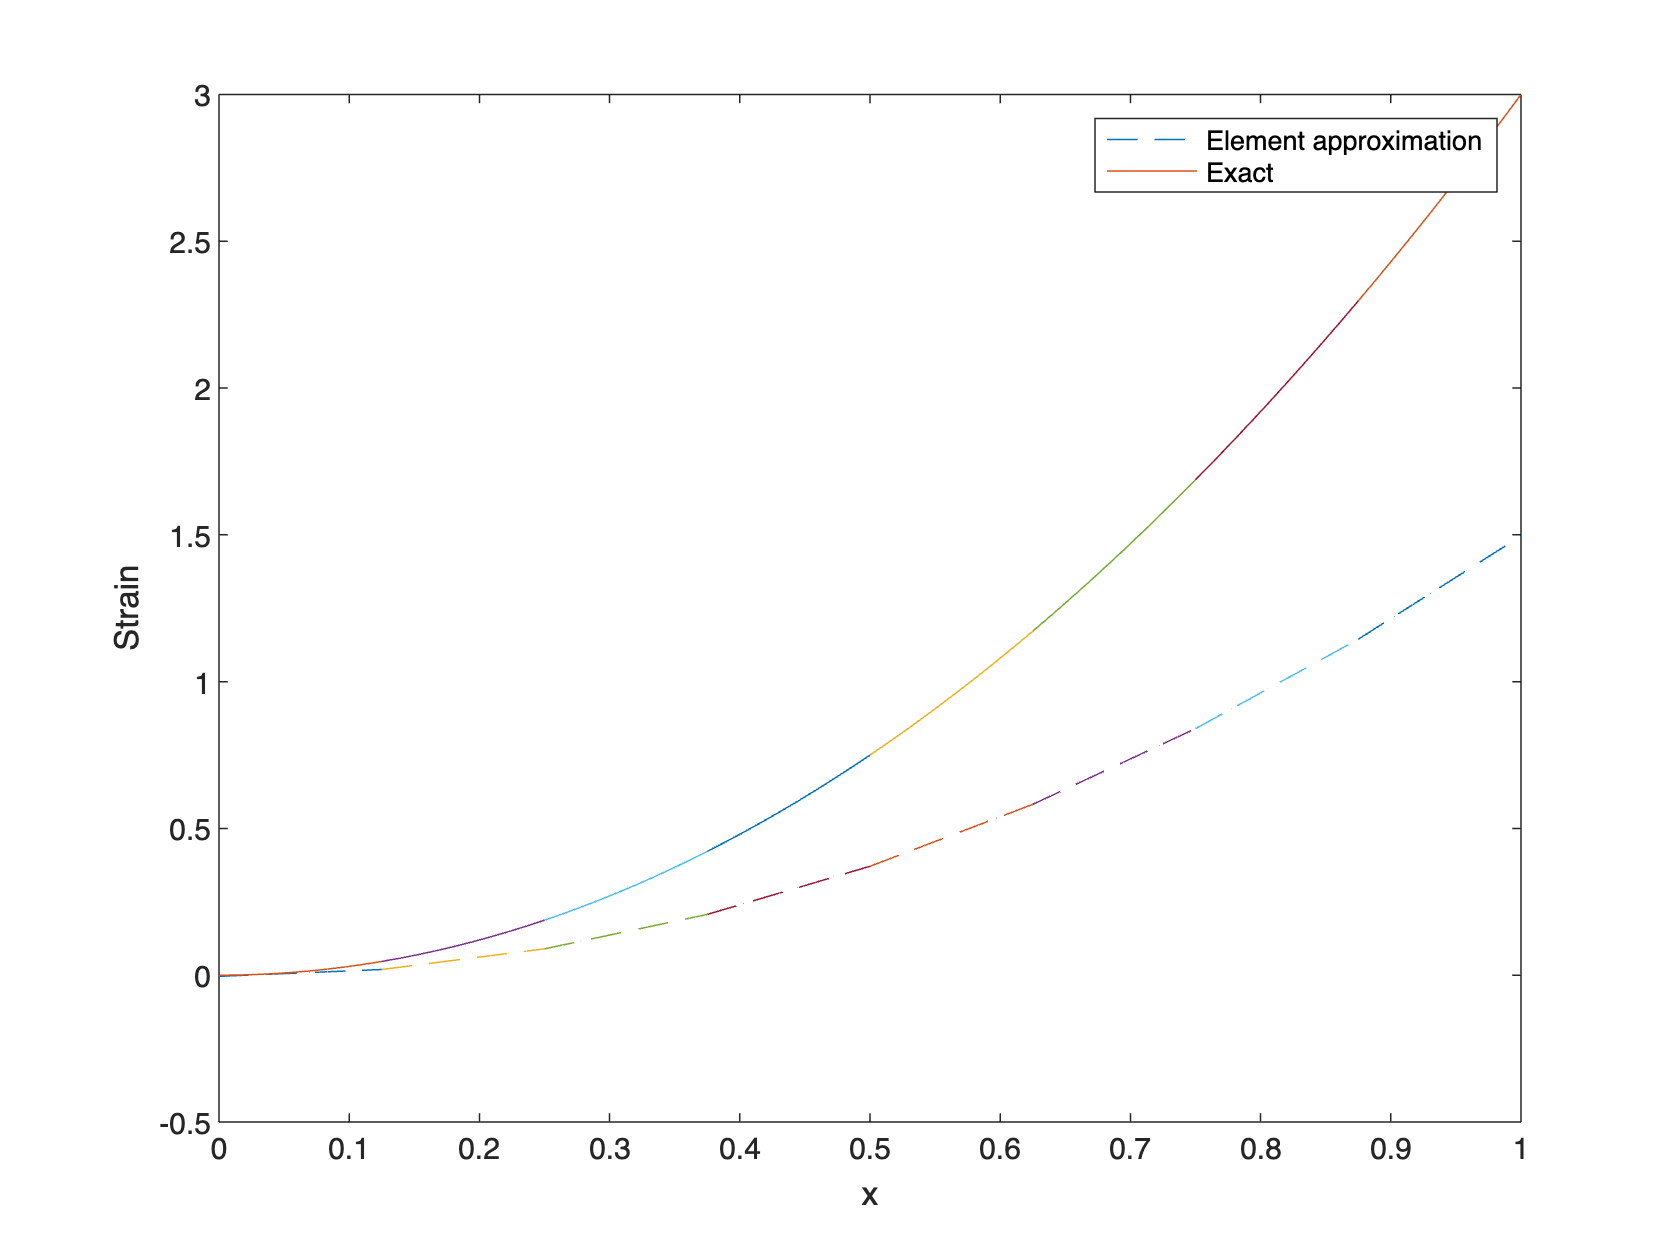

function [N, B] = shape1d_quad(x, xelem)

    % Quadratic shape functions for 3-node element
    le = xelem(3) - xelem(1);  % Element length
    xi = 2 * (x - xelem(1)) / le - 1;  % Parametric coordinate in [-1, 1]

    % Shape functions for 3-node quadratic element
    N = [(xi*(xi-1))/2, (1-xi^2), (xi*(xi+1))/2];

    % Derivative of shape functions (B matrix)
    B = [(xi - 0.5), -2*xi, (xi + 0.5)] / le;
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Code for HW Problem 4.4 (Modified for 3-noded quadratic elements)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
close all;
clear all;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% User input
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Element type
% etype=1: linear 2 node element
% etype=2: quadratic 3 node element
etype = 2;  % Changed to quadratic element (etype=2)

% Number of elements
Nelem = 8;

% Number of points to plot within each element
Npp = 10;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% End User input
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Domain length
L = 1.0;

% 1 dof per node
Ndof = 1;

% Nnodes: number of nodes per element
% Nnodes_g: number of global nodes
if etype == 1
    Nnodes = 2;
    Nnodes_g = Nelem + 1;
else
    Nnodes = 3;  % 3-node quadratic element
    Nnodes_g = 2 * Nelem + 1;  % Global nodes for quadratic elements
end

% Element length in 1D; constant throughout here
dx = L / Nelem;

% Spacing between plotting points (Gauss quadrature domain [-1,1])
dxi_plot = 2.0 / (Npp - 1);

% Initialize arrays for node coordinates
xyz = zeros(Nnodes_g, 3);
for i = 1:Nnodes_g
    xyz(i,1) = (i-1)*(dx/(Nnodes-1));
end

% Define element node to global node mapping (adjusted for 3-node element)
elem_map = zeros(Nelem, Nnodes);
for i = 1:Nelem
    for j = 1:Nnodes
        elem_map(i,j) = (i-1)*2 + j;  % Adjusted for quadratic elements
    end
end

% Define total number of global dof
Ndof_tot = Nnodes_g * Ndof;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Initialize all arrays with zeros
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
D = zeros(Ndof_tot,1);
ue = zeros(Nelem,Npp);
uexact = zeros(Nelem,Npp);
ee = zeros(Nelem,Npp);
eexact = zeros(Nelem,Npp);
xe = zeros(Nelem,Npp);
Delem = zeros(Nnodes,1);
xelem = zeros(Nnodes,1);
xi = zeros(4,1);

f1 = figure;
f2 = figure;
err2 = 0.0;

% Assign values to D based on exact solution u_I=x_I^3
for i = 1:Ndof_tot
    D(i) = xyz(i,1)^3;
end

% Loop over elements
for i = 1:Nelem

    % Assign nodal displacements and positions using elem_map
    for j = 1:Nnodes
        Delem(j,1) = D(elem_map(i,j));
        xelem(j,1) = xyz(elem_map(i,j));
    end

    % Loop over element plotting points
    for j = 1:Npp

        % Plotting point (in -1 to 1 domain)
        xi(1) = -1.0 + (j-1) * dxi_plot;

        % Compute shape function and B matrix
        if etype == 1
            xe(i,j) = xelem(1,1) * 0.5 * (1.0 - xi(1)) + xelem(2,1) * 0.5 * (1.0 + xi(1));
            [N, B] = shape1d_lin(xe(i,j), xelem);
        elseif etype == 2
            xe(i,j) = xelem(1,1) * 0.5 * (1.0 - xi(1)) + xelem(3,1) * 0.5 * (1.0 + xi(1));
            [N, B] = shape1d_quad(xe(i,j), xelem);  % Use quadratic shape function
        end

        % Displacement and strain at xe(j)
        ue(i,j) = N * Delem;
        uexact(i,j) = xe(i,j)^3;
        ee(i,j) = B * Delem;
        eexact(i,j) = 3.0 * xe(i,j)^2;
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Error calculation (Parts d and e)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % Use four-point Gauss quadrature for exact solution (cubic)
    w = [0.3478548451, 0.3478548451, 0.6521451549, 0.6521451549];
    xi = [0.8611363116, -0.8611363116, 0.3399810436, -0.3399810436];

    % Element length
    if etype == 1
        le = xelem(2) - xelem(1);
    else
        le = xelem(3) - xelem(1);
    end

    % Jacobian for transformation between x and xi
    Jac = 0.5 * le;

    % Loop over Gauss quad points
    for j = 1:4
        if etype == 1
            xg = xelem(1,1) * 0.5 * (1.0 - xi(j)) + xelem(2,1) * 0.5 * (1.0 + xi(j));
            [N, B] = shape1d_lin(xg, xelem);
        elseif etype == 2
            xg = xelem(1,1) * 0.5 * (1.0 - xi(j)) + xelem(3,1) * 0.5 * (1.0 + xi(j));
            [N, B] = shape1d_quad(xg, xelem);
        end

        % Approximation and exact solution at Gauss point
        ue_g = N * Delem;
        uexact_g = xg^3;

        % Compute error
        err2 = err2 + (uexact_g - ue_g)^2 * w(j) * Jac;
    end
end

% Plot results (parts a-c)
for i = 1:Nelem
    figure(f1)
    plot(xe(i,:), ue(i,:), '--', xe(i,:), uexact(i,:));
    legend('Element approximation', 'Exact');
    xlabel('x');
    ylabel('Displacement');
    hold on;
    figure(f2);
    plot(xe(i,:), ee(i,:), '--', xe(i,:), eexact(i,:));
    legend('Element approximation', 'Exact');
    xlabel('x');
    ylabel('Strain');
    hold on;
end

str = ['e2 = ', num2str(err2)];
disp(str);

e2 = 4.5413e-09
